close all
clc


## Settings


tratto1=2;
tratto2=2;
tratto3=2;
colore1 = [0.25 0.25 0.25];
colore2 = [0.5 0.5 0.5];
colore3 = [0.75 0.75 0.75];
t1s = t_ts_inv_sim(end) - Ns_inv*ts_inv;
t2s = t_ts_inv_sim(end);


fontsize_plotting = 12;


## Plotting

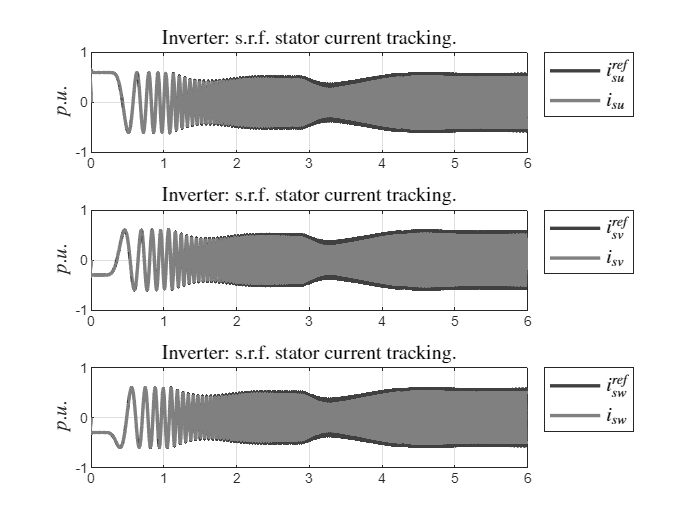

figure;
subplot 311
plot(t_ts_inv_sim,is_uvw_ref_pu_mod1_sim(:,1),'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(t_ts_inv_sim,is_uvw_pu_mod1_sim(:,1),'-','LineWidth',tratto1,'Color',colore2);
hold off
title('Inverter: s.r.f. stator current tracking.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{su}^{ref}$','$i_{su}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-1 1]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 312
plot(t_ts_inv_sim,is_uvw_ref_pu_mod1_sim(:,2),'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(t_ts_inv_sim,is_uvw_pu_mod1_sim(:,2),'-','LineWidth',tratto1,'Color',colore2);
hold off
title('Inverter: s.r.f. stator current tracking.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{sv}^{ref}$','$i_{sv}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-1 1]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 313
plot(t_ts_inv_sim,is_uvw_ref_pu_mod1_sim(:,3),'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(t_ts_inv_sim,is_uvw_pu_mod1_sim(:,3),'-','LineWidth',tratto1,'Color',colore2);
hold off
title('Inverter: s.r.f. stator current tracking.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{sw}^{ref}$','$i_{sw}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-1 1]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);

print('inverter_stator_current_tracking','-depsc');


return

figure;
subplot 211
plot(t_ts_inv_sim,is_xy_pu_mod1_sim(:,1),'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(t_ts_inv_sim,is_xy_pu_mod1_sim(:,2),'-','LineWidth',tratto1,'Color',colore2);
hold off
title('Inverter: s.r.f. stator currents.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{x}^{s}$','$i_{y}^{s}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-0.25 1]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 212
plot(t_ts_inv_sim,um_ctrl_out_mod1_sim,'-','LineWidth',tratto1,'Color',colore1);
hold on
plot(t_ts_inv_sim,ud_ctrl_out_mod1_sim,'-','LineWidth',tratto1,'Color',colore2);
hold on
plot(t_ts_inv_sim,uq_ctrl_out_mod1_sim,'-','LineWidth',tratto1,'Color',colore3);
hold off
title('Inverter: r.r.f. stator voltages.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$u_{m}$','$u_{d}$','$u_{q}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-1.25 1.25]);
set(gca,'xlim',[t1s t2s]);
grid on
% chH = get(gca,'Children');
% set(gca,'Children',[chH(1); chH(2); chH(3)]);
% grid on
% h=gcf;
% set(h,'PaperOrientation','landscape');
% set(h,'PaperUnits','normalized');
% set(h,'PaperPosition', [0 0 1 1]);
print('inverter_stator_current_voltage','-depsc');

figure;
subplot 211
plot(t_ts_inv_sim,psi_r_x_hat_mod1_sim,'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_ts_inv_sim,psi_r_y_hat_mod1_sim,'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Inverter: s.r.f. estimated stator fluxes.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$\hat{\psi}_{x}^{s}$','$\hat{\psi}_{y}^{s}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$\psi/Vs$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-0.25 1.5]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 212
plot(t_ts_inv_sim,omega_m_pu_mod1_sim,'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_ts_inv_sim,electromagnetic_torque_SI_im_sim./Tbez,'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Induction motor: mechanical quantities.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$\omega_{m}$','$\tau_e$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
xlabel('$t/s$','Interpreter','latex');
ylabel('$p.u.$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-0.25 1.75]);
set(gca,'xlim',[t1s t2s]);
grid on
% chH = get(gca,'Children');
% set(gca,'Children',[chH(1); chH(2); chH(3)]);
% grid on
% h=gcf;
% set(h,'PaperOrientation','landscape');
% set(h,'PaperUnits','normalized');
% set(h,'PaperPosition', [0 0 1 1]);
print('inverter_flux_estimated','-depsc');

figure;
subplot 211
plot(t_tc_sim,-psi_s_xy_im_sim(:,1),'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_tc_sim,-psi_s_xy_im_sim(:,2),'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Induction motor: s.r.f. stator fluxes.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$\psi_{x}^{s}$','$\psi_{y}^{s}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$\psi/Vs$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-0.25 2]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 212
plot(t_tc_sim,-psi_r_xy_im_sim(:,1),'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_tc_sim,-psi_r_xy_im_sim(:,2),'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Induction motor: s.r.f. rotor fluxes.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$\psi_{x}^{r}$','$\psi_{y}^{r}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
xlabel('$t/s$','Interpreter','latex');
ylabel('$\psi/Vs$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-0.25 2]);
set(gca,'xlim',[t1s t2s]);
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
grid on
% h=gcf;
% set(h,'PaperOrientation','landscape');
% set(h,'PaperUnits','normalized');
% set(h,'PaperPosition', [0 0 1 1]);
print('im_stator_rotor_fluxes','-depsc');

figure;
subplot 211
plot(t_tc_sim,-is_xy_im_sim(:,1),'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_tc_sim,-is_xy_im_sim(:,2),'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Induction motor: s.r.f. stator currents.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{x}^{s}$','$i_{y}^{s}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
% xlabel('$t/s$','Interpreter','latex');
ylabel('$i/A$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-200 850]);
set(gca,'xlim',[t1s t2s]);
grid on
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
subplot 212
plot(t_tc_sim,ir_xy_im_sim(:,1),'-','LineWidth',tratto2,'Color',colore1);
hold on
plot(t_tc_sim,ir_xy_im_sim(:,2),'-','LineWidth',tratto2,'Color',colore2);
hold off
title('Induction motor: s.r.f. rotor currents.','Interpreter','latex','FontSize',fontsize_plotting);
legend('$i_{x}^{r}$','$i_{y}^{r}$','Location','northeastoutside',...
    'Interpreter','latex','FontSize',fontsize_plotting);
xlabel('$t/s$','Interpreter','latex');
ylabel('$i/A$','Interpreter','latex','FontSize', fontsize_plotting);
set(gca,'ylim',[-200 850]);
set(gca,'xlim',[t1s t2s]);
chH = get(gca,'Children');
set(gca,'Children',[chH(1); chH(2)]);
grid on
% h=gcf;
% set(h,'PaperOrientation','landscape');
% set(h,'PaperUnits','normalized');
% set(h,'PaperPosition', [0 0 1 1]);
print('im_stator_rotor_currents','-depsc');